clear
close all
clc

**Valg af krydsfrekvens**

Der anvendes en switch-frekvens på 40 kHz. Der ønskes et maksimalt spændingsfald på 0,25V.

I_max = 1.5

I_max = 1.5000


L = 190 * 10^-6;
C = 220 * 10^-6;
f_s = 40000;
f_res = 1/(2*pi*sqrt(L*C))

f_res = 778.4523

Den maksimale øjeblikkelige ændring i strøm defineres som halvdelen af den maksimale DC-strøm

I_instant = 0.5 * I_max

I_instant = 0.7500

Krydsfrekvensen vælges og imdepancen i kondensatoren udregnes. Denne anvendes til at finde spændingsfaldet, når en strøm pludselig trækkes.

f_c = f_s/10

f_c = 4000

Z_c = 1/(i*2*pi*f_c*C);

dV = abs(I_instant * Z_c)

dV = 0.1356

Denne værdi, sammen med spændingsripplens højeste størrelse, må ikke være større end 0,25V.

**Udregning af reguleringskredsløb**

I følgende udregninger antages, at PWM-modulator-gain er lig 10, da TPS 40200-driveren holder den konstant, og K_fb = 1, da det er en spændingsdeling.

Der ønskes en fasemargin på mindst 60 grader. Spolens og kondensatorens ækvivalente modstande anvendes til udregningerne.

R_C = 0.09

R_C = 0.0900

R_L = 0.09

R_L = 0.0900

R = 5/1.5

R = 3.3333


Ph_margin = 60

Ph_margin = 60


G_filt = tf([(R*R_C*C) R],[(L*C*R+L*C*R_C) (R*R_C*C+L+R_L*C*R+R_L*C*R_C) (R+R_L)])


G_filt =
 
           6.6e-05 s + 3.333
  -----------------------------------
  1.431e-07 s^2 + 0.0003238 s + 3.423
 
Continuous-time transfer function.



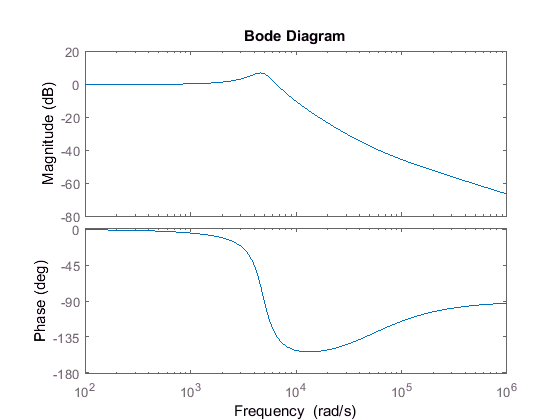

bodeplot(G_filt)


[filt_G_wc,filt_P_wc] = bode(10*G_filt,2*pi*f_c);
filt_P_wc

filt_P_wc = -148.1979

Det krævede fase-boost kan nu findes

Ph_boost = -90 + Ph_margin - filt_P_wc

Ph_boost = 118.1979

Det skal nu sikres, at den valgte frekvens rent faktisk er krydsfrekvensen. Dette gøres ved at sørge for, at overføringsfunktionernes amplituder ganget sammen giver 1, da dette svarer til 0 dB.

G_L_gain = G_C_gain * PWM_modulator_gain * G_filt_gain * Kfb

Her er PWM_modulator_gain 10 og Kfb er 1.

PWM_modulator_gain = 10

PWM_modulator_gain = 10

Kfb = 1

Kfb = 1

G_OL_gain = 1

G_OL_gain = 1

filt_G_wc

filt_G_wc = 0.4263


G_C_gain = G_OL_gain/(PWM_modulator_gain*filt_G_wc*Kfb)

G_C_gain = 0.2346

Der introduceres nu konstanten K_boost, der er defineret som den geometriske adskillelse mellem pol og nulpunkt i lead-regulatoren.

Der gælder, at K_boost = sqrt(f_p/f_z). Samtidig kan den også udregnes som

K_boost = tand(45+(Ph_boost/4))

K_boost = 3.6180

Dette anvendes derfor til at finde

f_z = f_c/K_boost

f_z = 1.1056e+03

f_p = K_boost*f_c

f_p = 1.4472e+04

Nu kan DC-forstærkningen til controlleren findes. Controlleren har overføringsfunktionen

G_C (s) = K_c/s * ((1+s/w_z)^2)/((1+s/w_p)^2)

K_c = G_C_gain * (2*pi*f_z)/K_boost

K_c = 450.4090

**Komponentvalg**

Herefter udregnes de påkrævede komponenter til regulatoren.

R9 skal vælges ud fra, hvor stor strøm vi ønsker. Den anvendes samtidig også til spændingsdelingen, der sørger for 5V som reference.

Vout = 5

Vout = 5

Vref = 0.696

Vref = 0.6960


R9 = 10000

R9 = 10000

R8 = (R9*Vref)/(Vout-Vref)

R8 = 1.6171e+03

Herefter kan de resterende komponenter findes. Ved hjælp af scriptet "round60063.m" findes de nærmest værdier i E-12-rækken (SMD-modstande) og E-3-rækken (SMD-kondensatorer). Hulkomponenter er hhv. E-24 og E-6.

C8 = (2*pi*f_z)/(K_c*2*pi*f_p*R9)

C8 = 1.6961e-08

C7 = C8*((2*pi*f_p)/(2*pi*f_z)-1)

C7 = 2.0506e-07

R7 = 1/(2*pi*f_z*C7)

R7 = 702.0221

R10 = R9/((2*pi*f_p)/(2*pi*f_z)-1)

R10 = 827.1280

C11 = 1/(2*pi*f_p*R10)

C11 = 1.3296e-08


R7_real = round60063(R7,'E12')

R7_real = 680

R8_real = round60063(R8,'E12')

R8_real = 1500

R9_real = round60063(R9,'E12')

R9_real = 10000

R10_real = round60063(R10,'E12')

R10_real = 820

C7_real = round60063(C7,'E3')

C7_real = 2.2000e-07

C8_real = round60063(C8,'E3')

C8_real = 2.2000e-08

C11_real = round60063(C11,'E3')

C11_real = 1.0000e-08

TEST:

s = tf('s');
H_s_teori = ((R7*C7*s+1)*(C11*(R9+R10)*s+1))/(s*R9*C7*(C8*R7*s+1)*(R10*C11*s+1))


H_s_teori =
 
       2.072e-08 s^2 + 0.0002879 s + 1
  ------------------------------------------
  2.685e-13 s^3 + 4.697e-08 s^2 + 0.002051 s
 
Continuous-time transfer function.



H_s_udregn = (450.4090*(1+s/(2*pi*1105.6))^2)/(s*(1+s/(2*pi*14472))^2)


H_s_udregn =
 
   3.724e12 s^2 + 5.174e16 s + 1.797e20
  ---------------------------------------
  4.826e07 s^3 + 8.776e12 s^2 + 3.99e17 s
 
Continuous-time transfer function.



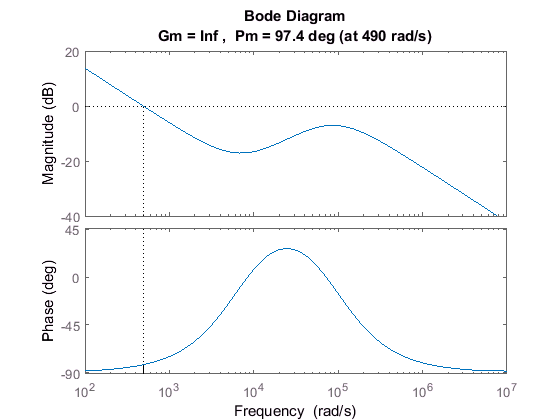


margin(H_s_teori)

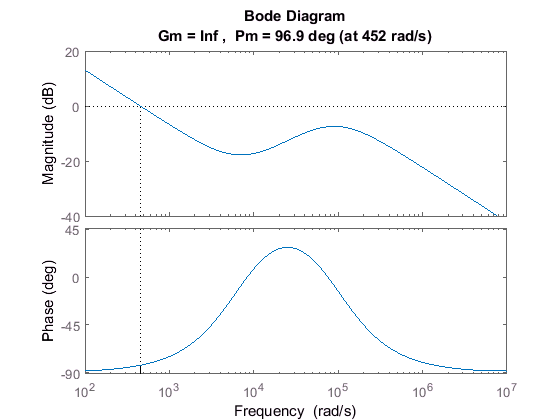

margin(H_s_udregn)